Christoffer Regnar Mølck

Nr: 202009347

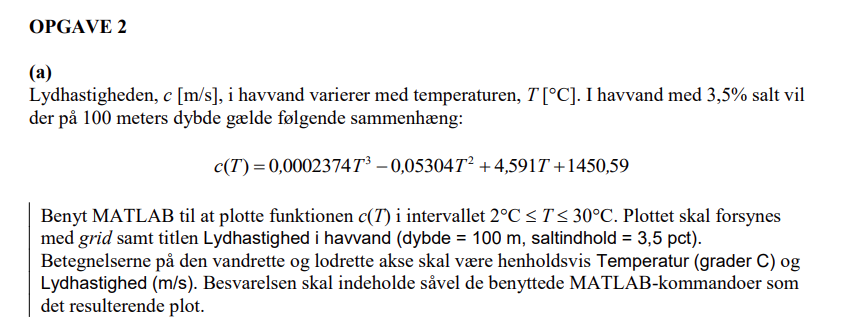

%Definere først funktionen
f = @(T) 0.0002374.*T.^3 - 0.05304.*T.^2 + 4.591.*T + 1450.59;


fplot(f,[2, 30]), grid; %Plotter funktionen
%Sætter titlen på plottet
title("Lydhastighed i havvand (dybde = 100 m, saltindhold = 3,5 pct)")

%sætter tekst på x aksen i latex 
xlabel("Temperatur ($^\circ C$)",'Interpreter','latex')

%sætter tekst på y aksen i latex 
ylabel("Lydhastighed $\left(\frac{m}{s}\right)$",'Interpreter','latex')

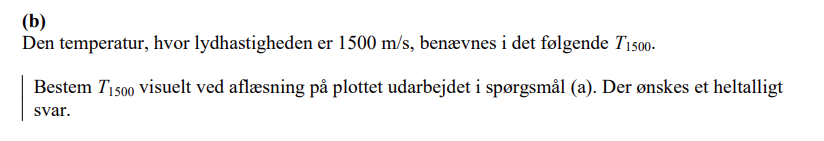

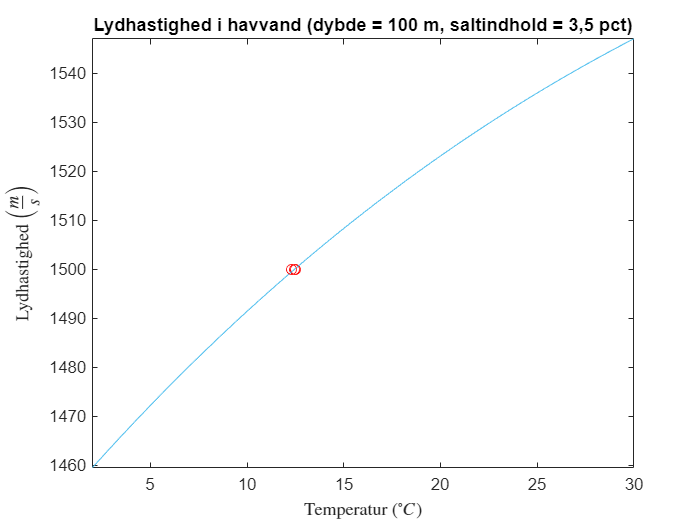

hold on %holder på plottet.
plot(12.3, 1500, 'ro') %Sætter en rød cirkel ved 1500 og cirkus på linjen. aflæses til 12c 

**Svaret på opgave b er altså 12c **

f = @(T) 0.0002374*T^3 - 0.05304*T^2 + 4.591*T + 1450.59 - 1500;
Tl = 10; % Nedre intervalendepunkt
Tu = 15; % Øvre intervalendepunkt
es = 0.01; % Ønsket nøjagtighed i %
maksit = 20; % max interationer
it = 0; % Startværdi for it
while 1
    Tr = (Tl + Tu)/2; %T værdien i roden
    ea = abs(Tr - Tl)/Tr*100; %usikkerheden
    it = it + 1; %iteration incrementer 
    if f(Tl)*f(Tr) > 0 
        Tu = Tr; %Der sættes nyt upper limit
    elseif f(Tl)*f(Tr) < 0
        Tl = Tr; %Der sættes nyt lower limit
    else
        ea = 0; %usikkerheden er 0 vis vi har ramt rigtigt. 
    end
    %Loopet stopes vis usikkerheden er mindre en nøjagtigheden eller vis
    %max antal iterationer opnås. 
    if ea <= es || it >= maksit, break, end
end
T1500 = Tr % Temperaturen 

T1500 = 12.5012

ea % Usikkerheden 

ea = 0.0098

it % Antal interationer der er kørt. 

it = 12

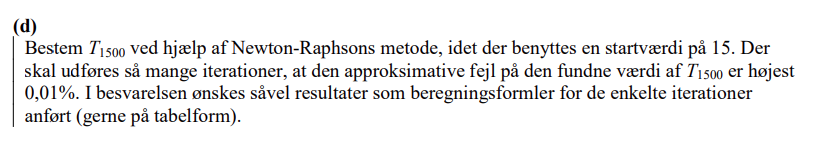

syms T %laver T til et symbol
f = 0.0002374.*T.^3 - 0.05304.*T.^2 + 4.591.*T + 1450.59 - 1500; 
newtraph(f, 15, 0.0001, 50)

root = 12.4545

ea = 1.0758e-09

iter = 4

tabel = 4×4 table
     Rod           f         df/dT       Error   
    ______    ___________    ______    __________

    12.366         8.3222      3.16        21.296
    12.454       -0.29811    3.3881       0.70649
    12.455    -0.00034229    3.3803    0.00081303
    12.455     -4.529e-10    3.3803    1.0758e-09


ans = 12.4545

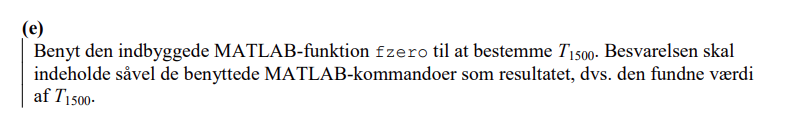

f = @(T) 0.0002374.*T.^3 - 0.05304.*T.^2 + 4.591.*T + 1450.59 - 1500; %definere

fzero(f,12) %finder der hvor funktionen er 0, start gæt = 12 

ans = 12.4545

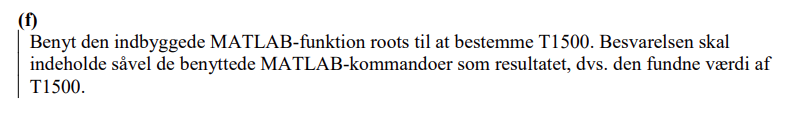

C = [0.0002374 -0.05304 4.591 1450.59-1500]; % array med constanterne
roots(C) % finder rødderne af polynomiet når konstanterne er gevet

ans = 1.0e+02 *

   1.0548 + 0.7473i
   1.0548 - 0.7473i
   0.1245 + 0.0000i


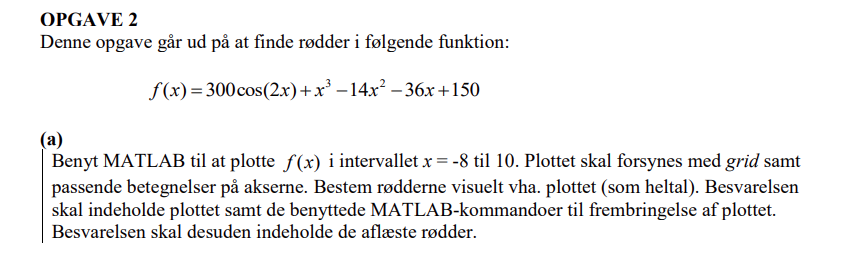

f = @(x) 300 .* cos(2.*x) + x.^3 - 14 .* x.^2 - 36 .*x + 150; %Function defineres
x = [-8 10] %Grenser

x =     -8    10


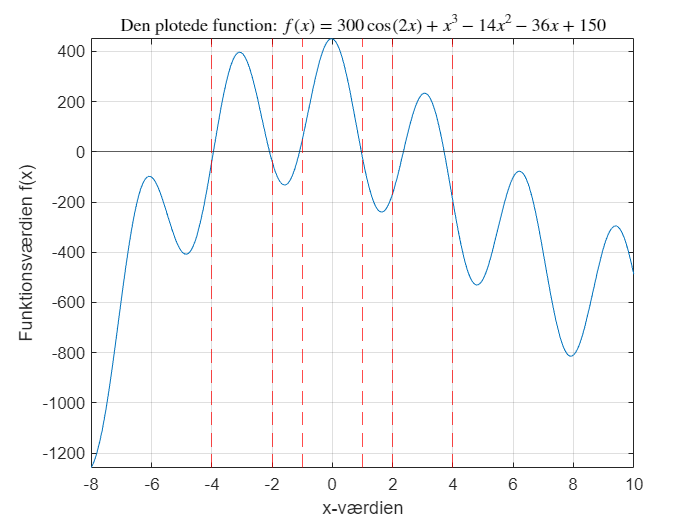

rod 1 aflæses til -4 
rod 2 aflæses til -2 
rod 3 aflæses til -1 
rod 4 aflæses til 1 
rod 5 aflæses til 2 


rod 6 aflæses til 4 


fplot(f, x), grid, yline(0) %plotter funktionen
title('Den plotede function: $f(x) = 300 \cos(2x) + x^3 - 14 x^2 - 36 x + 150$','Interpreter','latex') 
xlabel('x-værdien')
ylabel('Funktionsværdien f(x)')

rod = [-4 -2 -1 1 2 4]; %Visuelt aflæste rødder

%laver et forloop til markering af aflæste punkter kunne også gøres manuelt
%men et forloop er dejligt nemt. 
for i = 1:length(rod)
    xline(rod(i), '--r') %stiblet linje per rod
    fprintf('rod %g aflæses til %g \n', i, rod(i))
end

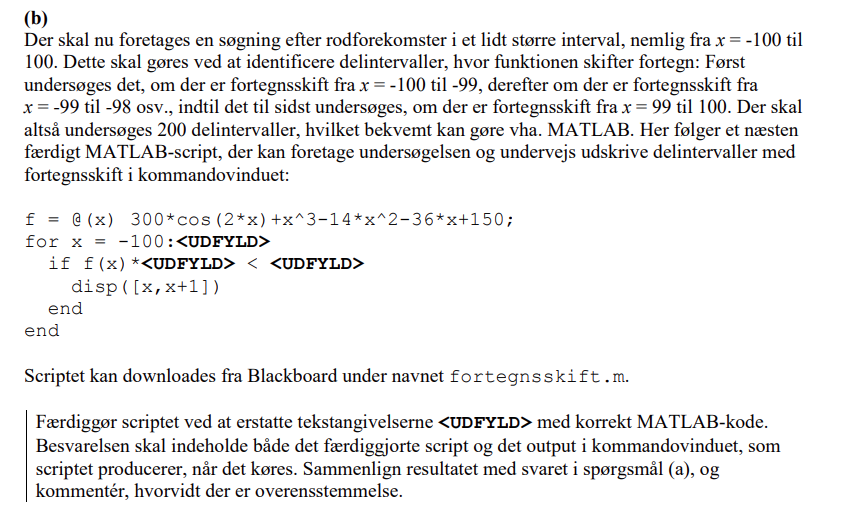

f = @(x) 300*cos(2*x)+x^3-14*x^2-36*x+150; %definer funktionen

%starter forloop
for x = -100:100 %Intervallet der ledes i
    if f(x)*f(x+1) < 0 %hvis de to funktions værdier har ens fortegn så sker der ikke nået
        disp([x,x+1]) % eller printes området
    end
end

    -4    -3

    -3    -2

    -2    -1

     0     1

     2     3

     3     4

    15    16



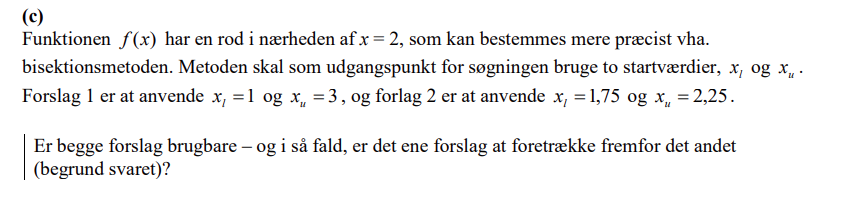

Tls = [1 1.75];
Tus = [3 2.25];
T1500s = [];
f = @(x) 300*cos(2*x)+x.^3-14*x.^2-36*x+150;

for i = 1:length(Tls)
    Tl = Tls(i); % Nedre intervalendepunkt
    Tu = Tus(i); % Øvre intervalendepunkt
    es = 0.01; % Ønsket nøjagtighed
    maksit = 20; % max it
    it = 0; % Startværdi for it
    while 1
        Tr = (Tl + Tu)/2; %T værdien
        ea = abs(Tr - Tl)/Tr*100; %usikkerheden
        it = it + 1; %iterationer
        if f(Tl)*f(Tr) < 0 
            Tu = Tr; %Der sættes nyt upper limit
        elseif f(Tl)*f(Tr) > 0
            Tl = Tr; %Der sættes nyt lower limit
        else
            ea = 0; %usikkerheden er 0 da vi er lige på
        end
        %Forloopet brydes hvis vi når et maksimalt antal forsøg eller vi kommer
        %indenfor usikkerheden.
        if ea <= es || it >= maksit
            break
        end
    end
    T1500 = Tr
    T1500s(end + 1) = T1500;
    
    ea % Usikkerheden
    it % Antal interationer 
if i == length(Tls)
    break
end
    disp(' ')
end

T1500 = 2.3551

ea = 0.0052

it = 14

T1500 = 2.2499

ea = 0.0054

it = 12

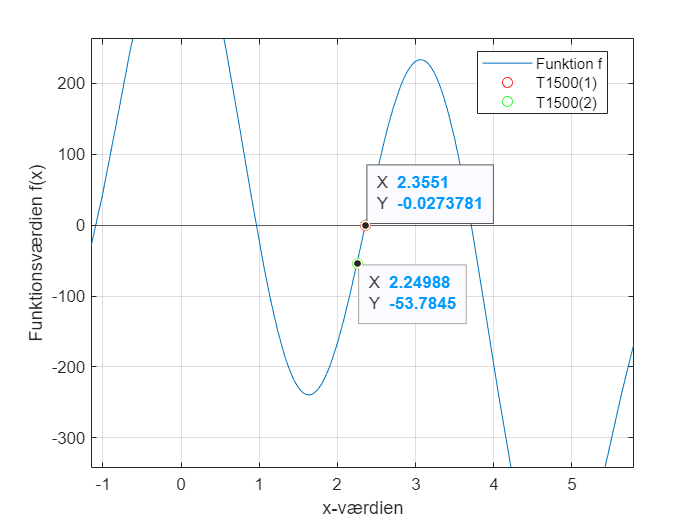

x = [-8 10];
f = @(x) 300 .* cos(2.*x) + x.^3 - 14 .* x.^2 - 36 .*x + 150;
fplot(f, x), grid, yline(0); %Vi plotter funktionen og tydliggør y=0
hold on

T1 = plot(T1500s(1), f(T1500s(1)), 'or','DisplayName', 'T1500(1)');
T2 = plot(T1500s(2), f(T1500s(2)), 'og','DisplayName', 'T1500(2)');

legend('Funktion f','', 'T1500(1)', 'T1500(2)', Location='best')
xlabel('x-værdien')
ylabel('Funktionsværdien f(x)')
xlim([-1.15 5.79])
ylim([-342 263])
zlim([-1.00 1.00])
ax = gca;
chart = ax.Children(1);
datatip(chart,2.25,-53.78,"Location","southeast");
chart = ax.Children(2);
datatip(chart,2.355,-0.02738);
hold off

Vi kan se at med t1500(2) er vi remt direkte ind i grænseværdigen på 2.25 hvilket ville sige at vi ikke kan bruge værdigen til så meget udover at vise at vi burde udvide vores grænser. værdig t1500(1) er dog imellem vores grænser og værdigen er derfor en rod. 

function [root,ea,iter]=newtraph(func,xr,es,maxit) 
% newtraph: Newton-Raphson root location zeroes 
%   [root,ea,iter]=newtraph(func,xr,es,maxit): 
%   uses Newton-Raphson method to find the root of func 
% input: 
%   func = name of function symbolic
%   xr = initial guess 
%   es = desired relative error (default = 0.0001%) 
%   maxit = maximum allowable iterations (default = 50) 
% output: 
%   root = real root 
%   ea = approximate relative error (%) 
%   iter = number of iterations 

if nargin<2 %Advar vis der ikke er nok inputs
    error('at least 2 input arguments required')
end 

if nargin<3||isempty(es) %Default value
    es=0.0001; 
end 

if nargin<4||isempty(maxit) %Default value
    maxit=50; 
end 

iter = 0; %iteration start
Resultat = [];
f_list = [];
df_list = [];
Error = [];

%differentier funktionen symbolsk og laver den numerisk igen
f = matlabFunction(func);
df = matlabFunction(diff(func)); 

while 1
  xrold = xr; %gemmer den gamle værdi
  xr = xr - f(xr)/df(xr); %udregner roden.

%   syms T %sætter T som et symbol til visning af ligningen
%   f_show = xr - f(T)/df(T) %ligningen der bruges
  iter = iter + 1; % antal gange der er kørt igennem
  
  Resultat(end+1) = xr; %tilføjer roden
  f_list(end+1) = f(xrold); %tilføjer ligningen
  df_list(end+1) = df(xrold);

  if xr ~= 0 %Hvis xr ikke er 0 sættes en ny error således undgår vi at 
      % dividere med 0
      ea = abs((xr - xrold)/xr) * 100; 
  end 
  Error(end+1) = ea;  %tilføjer error

  %while loopet stoppes hvis vi når inden for vores satte stat error eller
  %vi når det maximale antal iterrationer
  if ea <= es || iter >= maxit
      break
  end 
end
%Slut værdierne udprintes
root = xr
ea
iter

%Der laves en tabel med alle værdierne der er opnået
tabel = table(Resultat', f_list', df_list', Error',...
    VariableNames={'Rod','f', 'df/dT', ...
    'Error'})
end
